clear
close all
clc
delete(gcp('nocreate'))
tic


## load data and functions


DIR ='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/';
spec='Results_dock_time/Initial_vel_fluid/';
loadDIR=[DIR spec];

% Declare constants, load functions and data
Const = Constants;
fDIR=[DIR 'Functions/'];
addpath(fDIR)
load([loadDIR 'Dock_time_eps_00001_inorbit_katy.mat'])

saveDIR=[DIR,'Results_dock_approx/Rdot_gauss_approx/'];
savename='rdot_gauss_param.mat';

## choose plot parameters

fsize=16;
width=20;
height=25;
options=optimset('MaxFunEvals',100000000);

## data manipulation

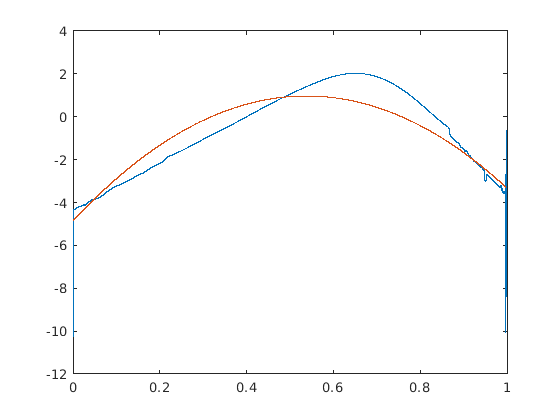


% choose relevant St/A values (for respective docking process)
npar=[];
param=zeros(1,numel(part));
for p=1:numel(part)
    param(p)=part(p).par.A^(-1)*part(p).par.St;
    if imag(texit(p))==0 && ~isnan(texit(p))
        npar=[npar,p];
    end
end

param_wyb=param(npar);
parmin=min(param_wyb);
parmax=max(param_wyb);
St_wyb=St(npar);
A_wyb=A(npar);
P_wyb=round(St_wyb./A_wyb);


for j=19%numel(npar)
    % j - number of the case chosen for the analysis, corresponding to the
    % docking process
    p=npar(j); % nr of particle out ot all the particles in this data
    
    xdata=part(p).traj.t/texit(p);
    rdotdata=smoothdata(part(p).traj.X(:,3)/(eps*A_wyb(j)),'lowess',500);
    x2data=xdata;
    x2data(rdotdata<0)=[];
    ydata=log(rdotdata);
    ydata(rdotdata<0)=[];
    P=polyfit(x2data,ydata,2);
    sigma(j)=(-2*P(1)).^(-1/2);
    mu(j)=-P(2)/(2*P(1));
    C(j)=exp(P(3)-P(2)^2/(4*P(1)));
    figure
    plot(xdata,log(rdotdata))
    hold on
    %plot(x2data,gauss(x2data,mu(j),sigma(j),C(j)))
    plot(x2data,P(1)*x2data.^2+P(2)*x2data+P(3))
    hold off
    %clear xdata x2data ydata p
end

toc

Elapsed time is 3.340534 seconds.


%delete(gcp('nocreate'))
%save([saveDIR savename])


%% Plot

% set(0,'DefaultAxesColor','none')
% clf
% figure(1)
% set(gcf,'Position', [640, 300, 2*560, 2*420 ],...
%             'paperunits','centimeters',...
%             'papersize',[width,height],...
%             'InvertHardCopy','off')
%         
% do_plot=(Rsq<=1).*(Rsq>0);
% xplot=P_wyb(do_plot==1);
% yplot1=muy(do_plot==1);
% yplot2=muy(do_plot==1);
% scatter(xplot,yplot1)

function wart=gauss(x,mu,sigma,C)
wart=C*exp(-(x-mu).^2./(2*sigma^2));
end